# Train Variational Autoencoder (VAE) for image generation and apply to anomaly detection

## Read the dataset

clear;clc;close all;rng(0);
training = true; % true: train network,   false: use trained network
% define imageDatastore
imds = imageDatastore('trainingimage','IncludeSubfolders',true);
imdsTrain = subset(imds,1:38); % Separate training data
imdsTest = subset(imds,39:40); % Separate test data

Imgsize = [720 1280]; % Image Size
BlockSize = [144  256]; % Input size of Network
numPatch =64;
% Use randomPatchExtractionDatastore for image augmentation
dsTrain = randomPatchExtractionDatastore(imdsTrain,imdsTrain,BlockSize,'PatchesPerImage',numPatch); 
dsTest = randomPatchExtractionDatastore(imdsTest,imdsTest,BlockSize,'PatchesPerImage',4); 

numTrainImages = numel(imdsTrain.Files);

## Create Network

latentDim = 20; % dimension of Latent space
imageSize = [BlockSize 3]; % Input size of Network
% Define an Encoder Network
encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')    
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);
% Define an Decoder Network
decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', [3 4], 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', [3 4], 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose4')
    reluLayer('Name','relu4')
    transposedConv2dLayer(3, 16, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose5')
    reluLayer('Name','relu5')
     transposedConv2dLayer(3, 16, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose6')
     reluLayer('Name','relu6')    
    transposedConv2dLayer(3, 3, 'Cropping', 'same', 'Name', 'transpose7')
    ]);

## Convert network into dlnetwork type

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

## Set training options

executionEnvironment = "auto"; % set execution environment

numEpochs = 400; % Num of epochs
miniBatchSize = numPatch; % mini Batch Size
lr = 1e-4; % Learning rate
numIterations = floor(numTrainImages/miniBatchSize); % Num of Iteration
iteration = 0;
dsTrain.MiniBatchSize = miniBatchSize;

% initialize the average gradient and the average gradient-square decay rates of adam optimizer with empty arrays
avgGradientsEncoder = [];
avgGradientsSquaredEncoder = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];

## Train the model

if training
for epoch = 1:numEpochs
    tic;
    for i = 1:numTrainImages
        iteration = iteration + 1;
        % read the training data and convert to dlarray
        PatchTrain = read(dsTrain);
        XBatch = PatchTrain.InputImage;
        XBatch = cat(4,XBatch{:});
        XBatch = dlarray(single(XBatch)/255, 'SSCB');
        % convert the image data to gpuArray, if the execution Environment is set to GPU
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            XBatch = gpuArray(XBatch);           
        end 
        % calculate gradient of loss
        [infGrad, genGrad] = dlfeval(...
            @modelGradients, encoderNet, decoderNet, XBatch);
        % update parameters of Encoder/Decoder
        [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
            adamupdate(decoderNet.Learnables, ...
                genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
        [encoderNet.Learnables, avgGradientsEncoder, avgGradientsSquaredEncoder] = ...
            adamupdate(encoderNet.Learnables, ...
                infGrad, avgGradientsEncoder, avgGradientsSquaredEncoder, iteration, lr);
    end
    elapsedTime = toc;
    % Reset the datastore object by each epoch
    reset(dsTrain);reset(dsTest);
    % test the model with unknown data
    PatchTest = read(dsTest);
    XTest= PatchTest.InputImage;
    XTest = dlarray(single(cat(4,XTest{:}))/255,'SSCB');
    % Predict the output
    [z, zMean, zLogvar] = sampling(encoderNet, XTest);
    xPred = sigmoid(forward(decoderNet, z));
    % Caluculate the Elbo loss
    elbo = ELBOloss(XTest, xPred, zMean, zLogvar);
    % show the results
    disp("Epoch : "+epoch+" Test ELBO loss = "+gather(extractdata(elbo))+...
        ". Time taken for epoch = "+ elapsedTime + "s")
    xPredout = uint8(gather(extractdata(xPred))*255);
    subplot(1,2,1);imshow(PatchTest.InputImage{1})
    subplot(1,2,2);imshow(xPredout(:,:,:,1));shg
end
    save(["net.mat"],'decoderNet','encoderNet'); % save the data
else
    load net
end

## Evaluate the model with images including foreign material

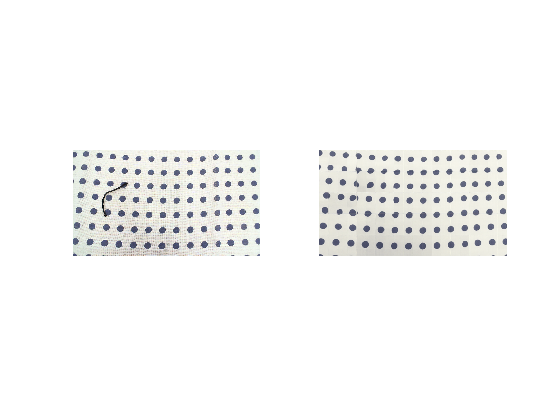

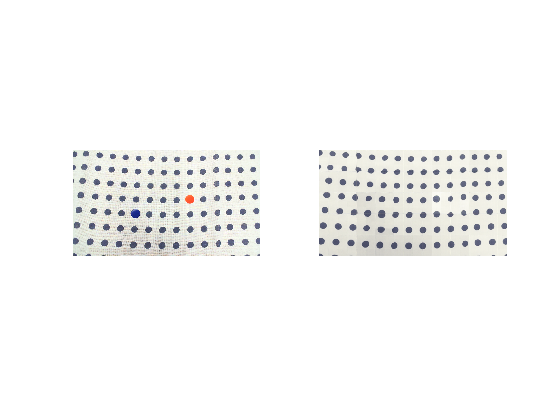

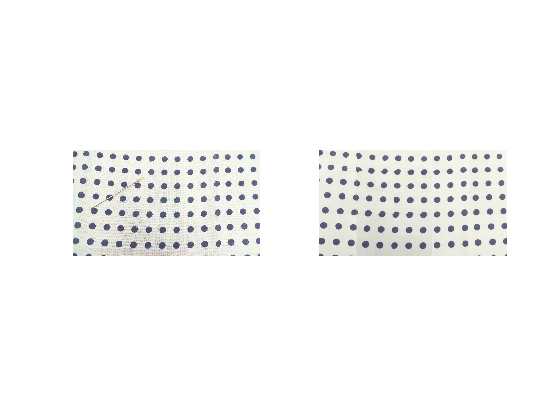

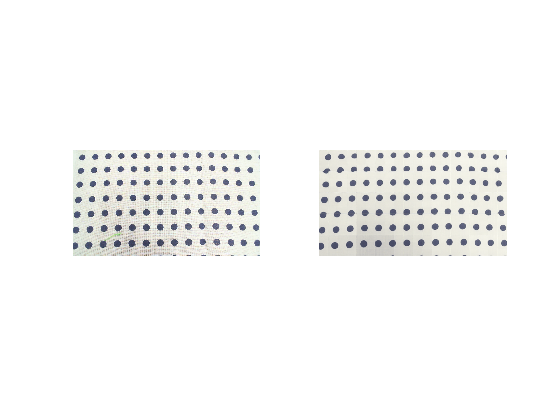

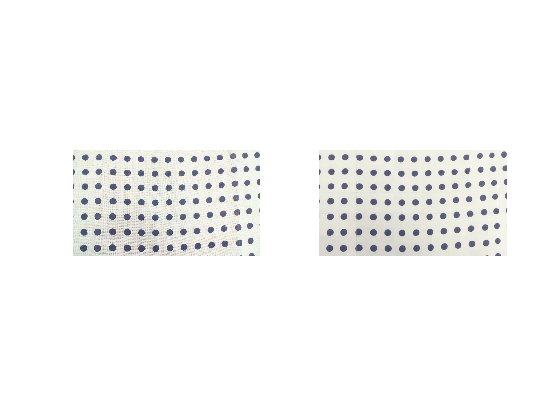

rng(0);
% Define image dataset for evaluation
imdsval = imageDatastore('testimage','IncludeSubfolders',true,'LabelSource','foldernames');
% set some variables
I_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
BW = logical(zeros(Imgsize(1),Imgsize(2),1,numel(imdsTest.Files)));
Predicted_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
I_big =uint8(zeros(Imgsize(1),Imgsize(2),3));
Predicted_big =uint8(zeros(720,1280,3));

for nn=1:numel(imdsval.Files)
    I_big = read(imdsval); % Read an image
    % Process in blocks for large images
    fun = @(block_struct) mypredict(encoderNet, decoderNet,block_struct);
    Predicted_big = gather(blockproc(I_big,BlockSize,fun));
    Predicted_big = uint8(Predicted_big*255);
    % get the difference between the inference result and the original image
    subt_temp = lab2rgb(imabsdiff( rgb2lab(I_big), rgb2lab(Predicted_big)));
    % Apply image processing algorithm to extract anomaly area
    BW_mask = Maskedge(Predicted_big);
    BW_temp= createMask(subt_temp);
    BW_temp = BW_temp & BW_mask;
    BW_temp = imfill(BW_temp,'holes'); 
    BW_temp = bwareaopen(BW_temp,400,4);

    % Catenate images and results
    I_All(:,:,:,nn) = I_big;
    Predicted_All(:,:,:,nn) = Predicted_big;
    BW(:,:,:,nn) = BW_temp;
    % Show the original image and inference image
    figure,
    subplot(1,2,1);imshow(I_big)
    subplot(1,2,2);imshow(Predicted_big);
%     subplot(2,2,3);imshow(subt_temp);    
%     subplot(2,2,4);imshow(BW_temp);
    shg
end

## Show the segmentation result

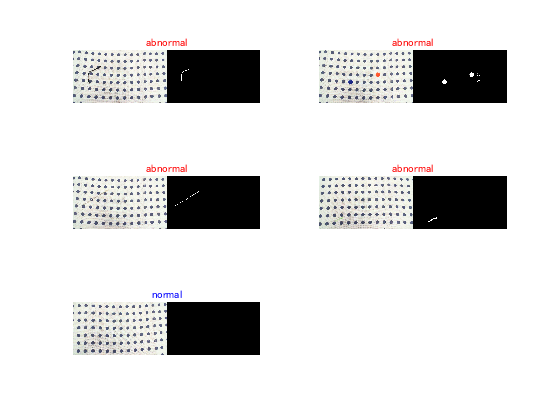

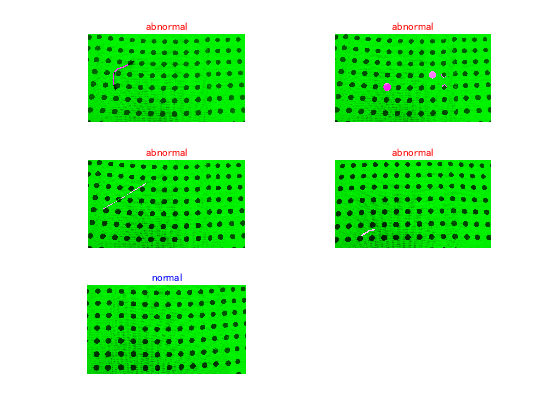

Color = {'r','r','r','r','b'};
f1 = figure;
f2 = figure;

for k = 1:numel(imdsval.Files)
    % show the result
    figure(f1), subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k),'montage');shg
    title(imdsval.Labels(k),'FontSize',20,'Color', Color{k});
    figure(f2),subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k));shg
    title(imdsval.Labels(k),'FontSize',20,'Color', Color{k});
end

## Helper function

The `modelGradients` function takes the encoder and decoder `dlnetwork` objects and a mini-batch of input data `X`, and returns the gradients of the loss with respect to the learnable parameters in the networks. The function performs three operations:

- Obtain the encodings by calling the `sampling` function on the mini-batch of images that passes through the encoder network.

- Obtain the loss by passing the encodings through the decoder network and calling the `ELBOloss` function.

- Compute the gradients of the loss with respect to the learnable paramaters of both networks by calling the `dlgradient` function.

function [infGrad, genGrad] = modelGradients(encoderNet, decoderNet, x)
[z, zMean, zLogvar] = sampling(encoderNet, x);
xPred = sigmoid(forward(decoderNet, z));
loss = ELBOloss(x, xPred, zMean, zLogvar);
[genGrad, infGrad] = dlgradient(loss, decoderNet.Learnables, ...
    encoderNet.Learnables);
end

%% Sampling Function
% The sampling function obtains encodings from input images. Initially, it passes a mini-batch of images
% through the encoder network and splits the output of size (2*latentDim)*miniBatchSize into a matrix of
% means and a matrix of variances, each of size latentDim*batchSize. Then, it uses these matrices to implement
% the reparametrization trick and to compute the encoding. Finally, it converts this encoding to a dlarray object
% in SSCB format.
function [zSampled, zMean, zLogvar] = sampling(encoderNet, x)
compressed = forward(encoderNet, x);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
zSampled = dlarray(z, 'SSCB');
end
% Loss Function
% The ELBOloss function takes the encodings of the means and the variances returned by the sampling function,
% and uses them to compute the ELBO loss.
function elbo = ELBOloss(x, xPred, zMean, zLogvar)
squares = 0.5*(xPred-x).^2;
reconstructionLoss  = sum(squares, [1,2,3]);
KL = -.5 * sum(1 + zLogvar - zMean.^2 - exp(zLogvar), 1);
elbo = mean(reconstructionLoss + KL);
end
% predict function
function xPred = mypredict(encoderNet, decoderNet, block_struct)
    XEval = dlarray(single(imresize(block_struct.data,[144 256]))/255,'SSC');
    [z, ~, ~] = sampling(encoderNet, XEval);
    xPred = sigmoid(forward(decoderNet, z));
    xPred = extractdata(xPred);
end

% Functions for postprocessing
% Function to make a mask around the pattern
function BW = Maskedge(RGB)
I = rgb2hsv(RGB);
% Define thresholds for Hue based on histogram settings
channel1Min = 0.545;
channel1Max = 0.801;
% Define thresholds for Saturation based on histogram settings
channel2Min = 0.138;
channel2Max = 1.000;
% Define thresholds for Value based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;

% create a mask
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW1 = sliderBW;
% apply morphological processing
BW1 = imfill(BW1,'holes');
BW_L = imdilate(BW1,strel('disk',2,4));
BW_S = imerode(BW1,strel('disk',10,4));
BW = ~BW_L;
end

% the function to extract anomaly area
function BW = createMask(RGB)
RGB = mat2gray(RGB);
I = rgb2hsv(RGB);
% Define thresholds for Hue based on histogram settings
channel1Min = 0.000;
channel1Max = 1.000;
% Define thresholds for Saturation based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;
% Define thresholds for Value based on histogram settings
channel3Min = 0.315;
channel3Max = 1.000;
% create a mask
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
end

*Copyright 2019 The MathWorks, Inc.*